# **Procesarea imaginilor - Transformari geometrice**

## **Notiuni generale**

- eliminarea distorsiunilor

- compararea imaginilor obtinute de dispozitive diferite

###     a. Transformarea coordonatelor pixeilor imaginii initiale

- **Tx(x, y) = x' => Ty(x, y) = y';**

- transformarea **pixelilor imaginii initiale** in **pixelii imaginii transformate**

#### **        Transformarea biliniara => 4 perechi de puncte pentru a determina coeficientii**

**        -> **Pentru a putea determina valoarea unui pixel nou in urma unei transformari, sunt necesari 4 pixeli din imaginea initiala pentru a calcula o medie ponderata

#### **        Transformarea afina => 3 perechi de puncte pentru a determina coeficientii**

#### **        Transformarea sistemului de coodronate: Jacobianul**

- **        J = 0 => **nu exista transformare inversa

-         **J = 1 => **aria este invarianta la transformare

        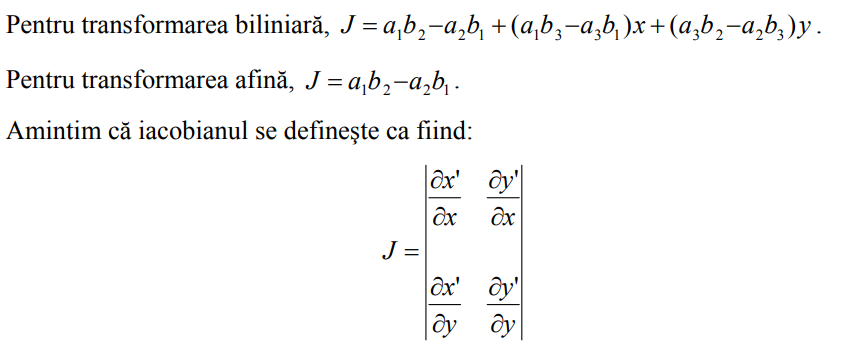

####           **Transformari utile**

###                 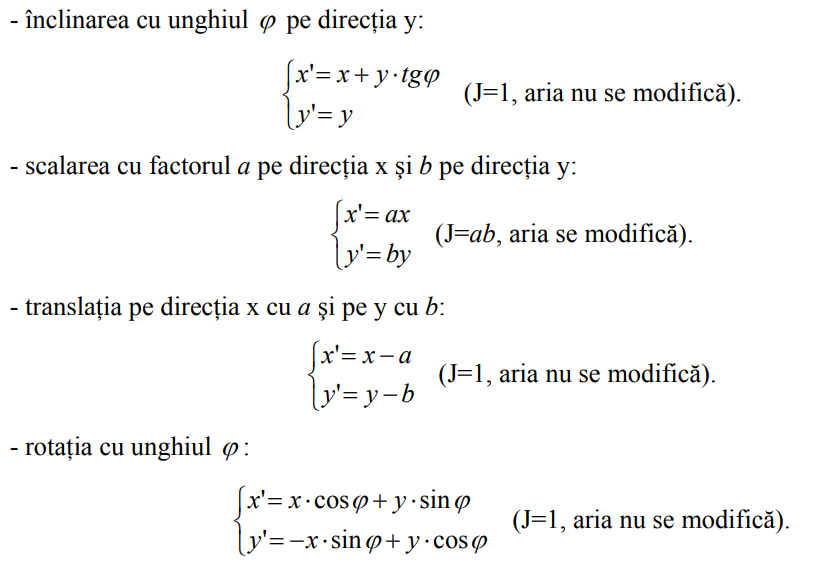

###     b. Calcularea nivelurilor de gri ale pixelilor noii imagini aka Interpolare

-         Imaginați-vă că aveți o **imagine mică** și doriți să **o faceți mai mare => **e nevoie de mai multe informații despre cum arată imaginea la dimensiunile mai mari **=> **umplem golurile pe baza informatiilor deja existente

 **Exemplu concret**: imaginați-vă că aveți doar cateva puncte pe un grafic și doriți să trasați o linie netedă între ele. Interpolarea vă permite să estimați valorile punctelor intermediare pentru a obține o linie continuă.

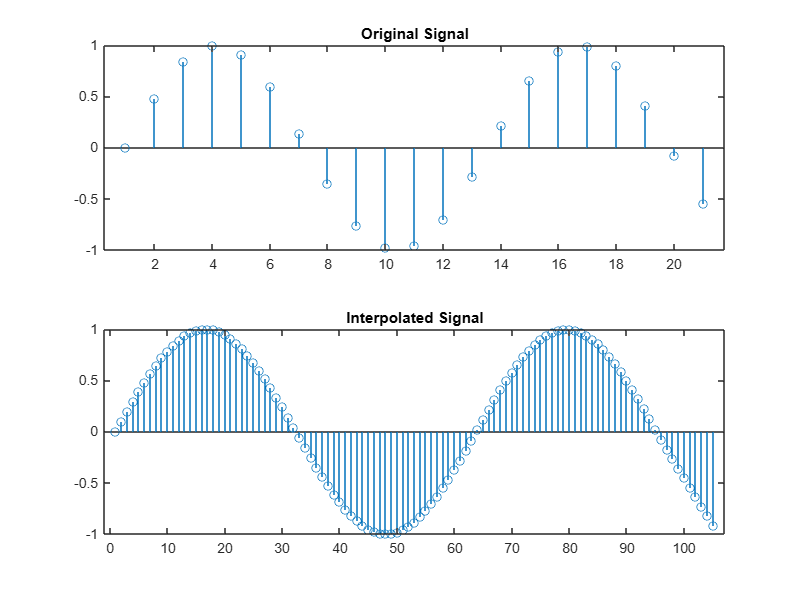

t = 0:0.5:10;           % Time signal
x = sin(t);             % Original Signal
y = interp(x,5);        % Interpolated Signal
subplot(211);
stem(x);
title('Original Signal');
subplot(212);
stem(y); 
title('Interpolated Signal');

În contextul imaginilor, interpolarea ajută la estimarea valorilor de pixel între pozițiile discrete cunoscute. De exemplu, când scalăm o imagine, nu avem informații despre cum arată pixelii noi între cei existenți. Interpolarea ne ajută să esti­măm aceste valori noi, astfel încât imaginea să pară netedă și fără artefacte.

Multiple **metode de interpolare: **

- **metoda vecinului cel mai apropiat: **aproximare pe baza valorii celei mai apropiate pozitii deja cunoscute

- **interpolarea biliniară:** se aproximeaza valoarea pe baza unei medii ponderate intre 4 pixeli vecini

- **interpolarea cubică: **se aproximeaza valoarea pe baza ajustarii unei functii polinomiale de gradul 3

### Matlab functions

initial = imread('coins.png');

## imresize

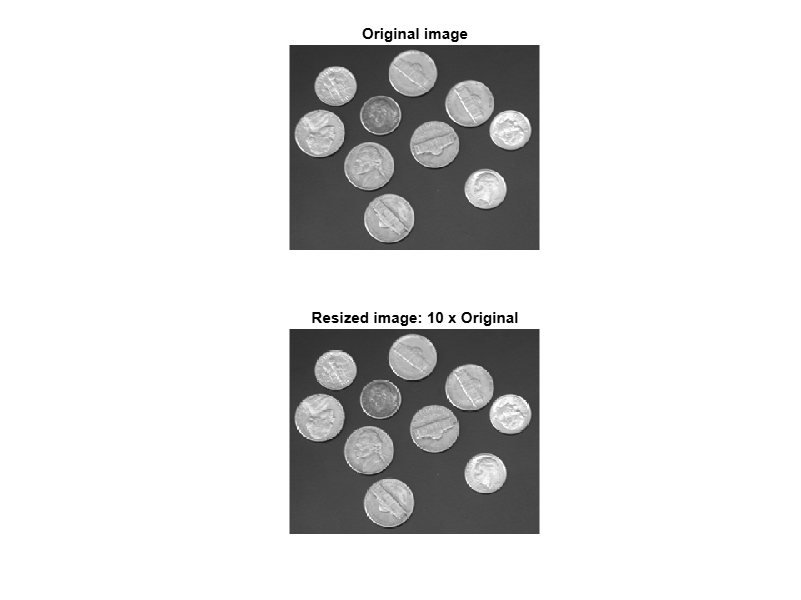

resized = imresize(initial, 10, "nearest");
figure(1)
subplot(2, 1, 1)
imshow(initial)
title("Original image")
subplot(2, 1, 2)
imshow(resized)
title("Resized image: 10 x Original")

## imrotate

rotated = imrotate(initial, 45);
figure(2)
subplot(2, 1, 1)
imshow(initial)
title("Original image")
subplot(2, 1, 2)
imshow(rotated)
title("Rotated image by 45 deg")

## imcrop

cropped = imcrop(initial, [100 100 100 100]);
figure(2)
subplot(2, 1, 1)
imshow(initial)
title("Original image")
subplot(2, 1, 2)
imshow(cropped)
title("Cropped image")


## maketform

% use help and implement the examples from there
help maketform


## cp2tform

% use help and implement the examples from there
help cp2tform


## imtransform

% use help and implement the examples from there
help imtransform

## example

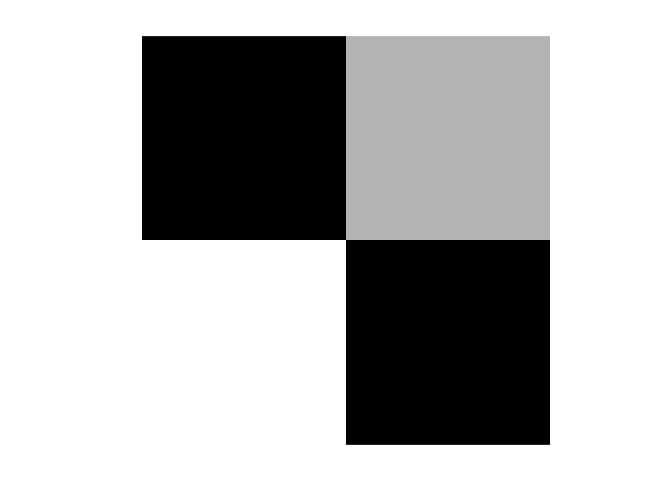

I = checkerboard(20,1,1);
figure; imshow(I)

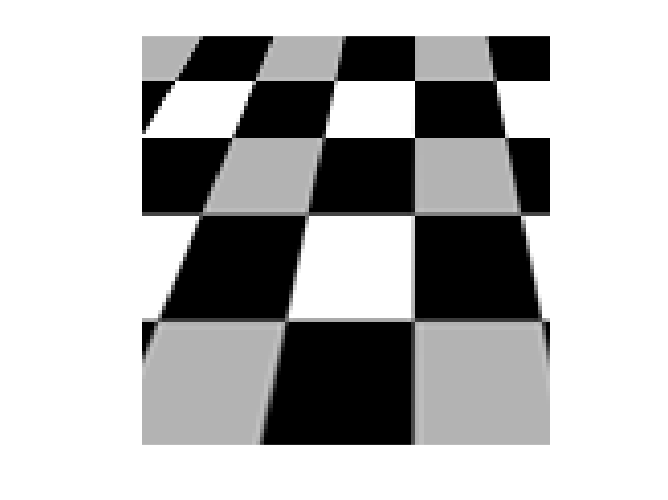

T = maketform('projective',[1 1; 41 1; 41 41; 1 41],...
[5 5; 40 5; 35 30; -10 30]);
R = makeresampler('cubic','circular');
K = imtransform(I,T,R,'Size',[100 100],'XYScale',1);
figure, imshow(K) 

## Exercitiul 1

%% Realizaţi o funcţie de scalare (redimensionare), 
%utilizând metoda de interpolare a
%vecinului cel mai apropiat

factorDeScalare = 2;
rez = redimensionare(initial, factorDeScalare);
figure();
subplot(1,2,1);
imshow(initial);
subplot(1,2,2);
imshow(rez);

I = imread('coins.png');
V = interp2(I,'nearest');
% figure;imshow(V);
figure();
subplot(1,2,1);
imshow(I);
subplot(1,2,2);
imshow(V);


## Exercitiul 2

% Scrieţi o funcţie Matlab care să realizeze rotaţia 
% unei imagini grayscale cu un anumit unghi primit ca parametru 

I = imread('peppers.png');
J = rgb2gray(I);
unghi = -30;
K = imrotate(J,unghi, "nearest");
figure;imshow(K);


## Exercitiul 3

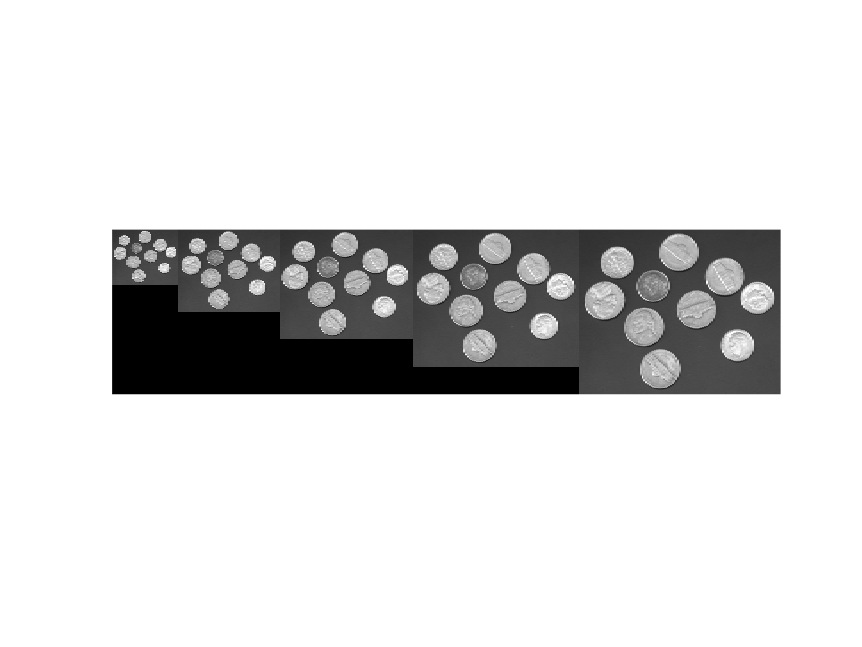

im = imread('coins.png');
[m,n] = size(im);










[rez, images] = pyramidScale(im, 3, 0.5);
figure; imshow(uint8(rez));

function [rez, images] = pyramidScale(image, nrScales, stepScale)
    % vector de scalare
    scaleOfImages = 1:stepScale:nrScales;
    % vectori pentru dimensiuni
    m = zeros(length(scaleOfImages), 1);
    n = zeros(length(scaleOfImages), 1);
    % cell array pentru imagini
    images = {};
    
    for i = 1:length(scaleOfImages)
        tempIm = imresize(image, scaleOfImages(i)); % Scalarea cu factorul corespunzător
        [m1, n1] = size(tempIm);
        m(i) = m1;
        n(i) = n1;
        images{i} = tempIm;
    end

    % creare matrice globala/aia mare
    rez = zeros(m(end), n(end)); % Inițializarea matricei rez cu dimensiunile corecte
    % initializare doi indici
    k1 = 1;
    k2 = n(1);
    for i = 2:length(m)
        rez(1:m(i-1), k1:k2) = images{i-1}; % Combinarea imaginilor scalate
        k1 = k1 + n(i-1);
        k2 = k2 + n(i);
    end
    % final assignment
    rez(1:m(length(scaleOfImages)), (k1):(k2)) = images{end}; % Combinarea imaginilor scalate
end

function scaledImage = redimensionare(inputImage, scaleFactor)
    % Get the size of the input image
    [rows, cols, channels] = size(inputImage);
    
    % Calculate the size of the scaled image
    newRows = round(rows * scaleFactor);
    newCols = round(cols * scaleFactor);
    
    % Create a grid of coordinates for the scaled image
    [X, Y] = meshgrid(1:newCols, 1:newRows);
    
    % Calculate the corresponding coordinates in the input image
    origX = min(max(round(X / scaleFactor), 1), cols);
    origY = min(max(round(Y / scaleFactor), 1), rows);
    
    % Initialize the scaled image
    scaledImage = zeros(newRows, newCols, channels, class(inputImage));
    
    % Perform nearest neighbor interpolation for each color channel
    for k = 1:channels
        scaledImage(:,:,k) = inputImage(origY + (origX - 1) * rows + (k - 1) * rows * cols);
    end
end



## Pentru cei care au terminat

% Scurta introducere in AppDesigner
% appdesigner